# Gazebo Simulations

## Clear Previous Data

clear;
close;
clc;

## Initialize ROS

rosshutdown;
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_92620 with NodeURI http://ROS-1-Ubuntu:36609/ and MasterURI http://localhost:11311.


## Fetch Parameters from ROS

JointStates = rossubscriber('/rrbot/joint_states');
client = rossvcclient('/gazebo/set_model_configuration');
req = rosmessage(client);
req.ModelName = 'rrbot';
req.UrdfParamName = 'robot_description';
req.JointNames = {'joint1','joint2'};
req.JointPositions = [deg2rad(30), deg2rad(45)];
resp = call(client,req,'Timeout',3);
tic;
t = 0;
i = 1;
while(t < 10)
    t = toc;
    % read the joint states
    jointData = receive(JointStates);
    % inspect the "jointData" variable in MATLAB to get familiar with its structure
    % sample the time and joint state values here to be plotted at the end

## Collect Data from ROS Sensors

    time(i,1) =t;
    theta(i,1) = jointData.Position(1,1);
    theta(i,2) = jointData.Position(2,1);
    velocity(i,1) = jointData.Velocity(1,1);
    velocity(i,2) = jointData.Velocity(2,1);
    i=i+1;
end

## Disconnect from roscore

rosshutdown;

Shutting down global node /matlab_global_node_92620 with NodeURI http://ROS-1-Ubuntu:36609/ and MasterURI http://localhost:11311.


## Plot the trajectories

bar_length = [1;1];
r_size = i-1;
position = zeros(r_size,4);
for i = 1:r_size(1,1)
    position(i,1) = bar_length(1,1)*sin(theta(i,1));
    position(i,2) = bar_length(1,1)*cos(theta(i,1));
    position(i,3) = position(i,1) + bar_length(2,1)*sin(theta(i,1) + theta(i,2));
    position(i,4) = position(i,2) + bar_length(2,1)*cos(theta(i,1) + theta(i,2));
end

## Animation

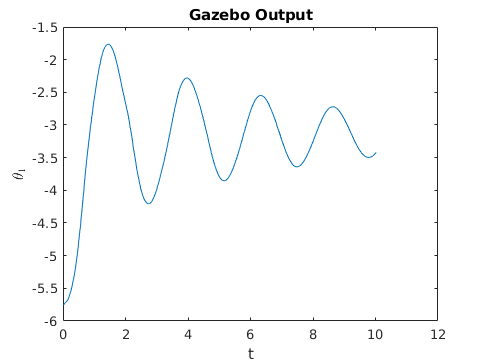

xAxisArrayXCoordinates = [-2 2];
xAxisArrayYCoordinates = [0 0];
yAxisArrayXCoordinates = [0 0];
yAxisArrayYCoordinates = [-2 2];
th = 0:pi/50:2*pi;
xunit = (bar_length(1,1) + bar_length(2,1)) * cos(th);
yunit = (bar_length(1,1) + bar_length(2,1)) * sin(th);
plot(time(:,1),theta(:,1))
xlabel('t')
ylabel('${\theta_1}$', 'Interpreter','latex')
title('Gazebo Output')
saveas(gcf,'theta1.jpg')

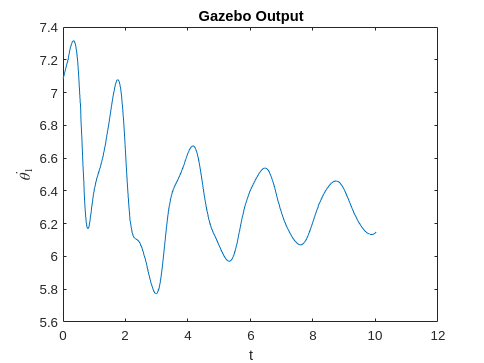

plot(time(:,1),theta(:,2))
xlabel('t')
ylabel('$\dot{\theta_1}$', 'Interpreter','latex')
title('Gazebo Output')
saveas(gcf,'theta_dot_1.jpg')

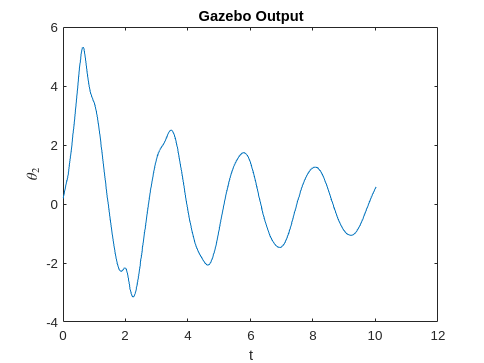

plot(time(:,1),velocity(:,1))
xlabel('t')
ylabel('${\theta_2}$', 'Interpreter','latex')
title('Gazebo Output')
saveas(gcf,'theta2.jpg')

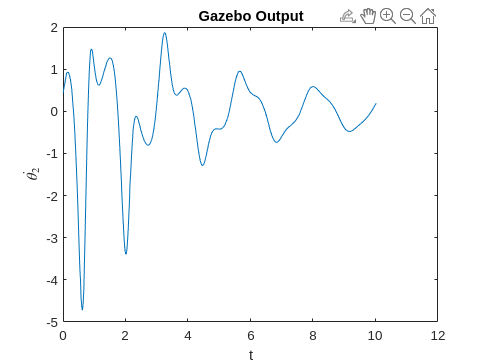

plot(time(:,1),velocity(:,2))
xlabel('t')
ylabel('$\dot{\theta_2}$', 'Interpreter','latex')
title('Gazebo Output')
saveas(gcf,'theta_dot_2.jpg')

delete('Gazebo Simulation.avi');

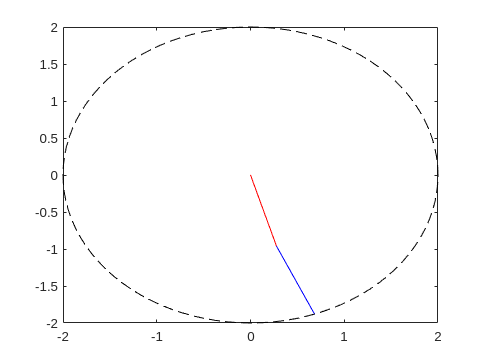

animation = VideoWriter('Gazebo Simulation.avi');
open(animation);
for i = 1:1:r_size(1,1)
    %Plotting Graph
    link1XCoordinates = [0 position(i,1)];
    link1YCoordinates = [0 position(i,2)];
    link2XCoordinates = [position(i,1) position(i,3)];
    link2YCoordinates = [position(i,2) position(i,4)];
    plot(xunit, yunit,'k','LineStyle','--'); % Draw Circular Axes
    hold on;
    plot(link1XCoordinates, link1YCoordinates, 'red');
    plot(link2XCoordinates, link2YCoordinates, 'blue');
    frame = getframe(gcf);
    writeVideo(animation,frame);
    pause(0.1); % pause to see realtime animation. Given in seconds
    hold off;
end

close(animation);